# EE3TP3 Lab 1 

#### 1A

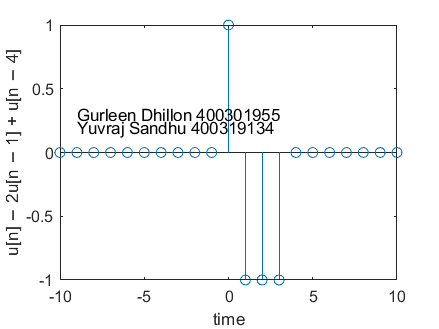

clear
 %creating a SimpleFunctions object
t = -10:10;
f = SimpleFunctions;

%plotting the discrete time function x1
x1 = f.unitstep(t) - 2*f.unitstep(t-1) + f.unitstep(t-4);
stem(t,x1)
xlabel('time')
ylabel('u[n] − 2u[n − 1] + u[n − 4]')
text(-9,0.3,'Gurleen Dhillon 400301955');
text(-9,0.2,'Yuvraj Sandhu 400319134');
exportgraphics(gcf, '3tp3_lab1_1a.jpg');

#### 1B

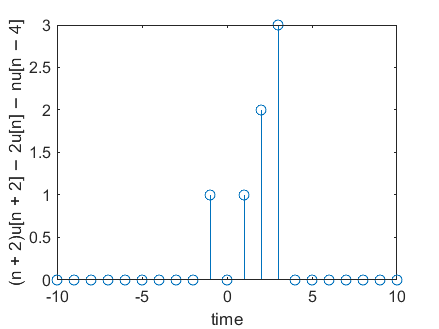

clear
%creating a SimpleFunctions object
t = -10:10;
f = SimpleFunctions;

%plotting the discrete time function x2
x2 = (t + 2).*(f.unitstep(t + 2)) - 2.*f.unitstep(t) - t.*f.unitstep(t - 4);
stem(t, x2)
xlabel('time')
ylabel('(n + 2)u[n + 2] − 2u[n] − nu[n − 4]')
text(-9,9,'Gurleen Dhillon 400301955');
text(-9,8,'Yuvraj Sandhu 400319134');
exportgraphics(gcf, '3tp3_lab1_1b.jpg');

#### 1C

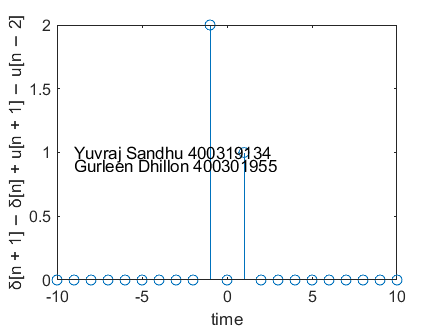

clear
%creating a SimpleFunctions object
t = -10:10;
f = SimpleFunctions;

%plotting the discrete time function x3
x3 = f.delta(t + 1) - f.delta(t) + f.unitstep(t + 1) - f.unitstep(t - 2);
stem(t, x3)
xlabel('time')
ylabel('δ[n + 1] − δ[n] + u[n + 1] − u[n − 2]')
text(-9,0.9,'Gurleen Dhillon 400301955');
text(-9,1,'Yuvraj Sandhu 400319134');
exportgraphics(gcf, '3tp3_lab1_1c.jpg');

#### 1D

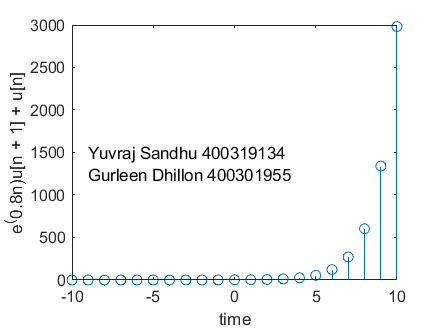

clear
%creating a SimpleFunctions object
t = -10:10;
f = SimpleFunctions;

%plotting the discrete time function x4
x4 = (exp(0.8*t).*f.unitstep(t + 1)) + f.unitstep(t);
stem(t, x4)
xlabel('time')
ylabel('e^(0.8n)u[n + 1] + u[n]')
text(-9, 1250,'Gurleen Dhillon 400301955');
text(-9,1500,'Yuvraj Sandhu 400319134');
exportgraphics(gcf, '3tp3_lab1_1d.jpg');

#### 2A

clear
%opening excel file
opts = detectImportOptions('course_grades_2022.xlsx');
opts = setvartype(opts, {'ID_Number', 'Name'}, 'string');
table = readtable('course_grades_2022.xlsx', opts);

%save lab marks from table as local variables
lab1 = table.Lab_1(2:end);
lab2 = table.Lab_2(2:end);
lab3 = table.Lab_3(2:end);
lab4 = table.Lab_4(2:end);

total_marks = lab1 + lab2 + lab3 + lab4; %add all lab marks

[highest_mark, i] = max(total_marks); %finding highest mark and saving the number and its index
highest_name = table.Name(i+1) %using the index to find the name and dispaly it

highest_name = "Gurleen Dhillon"

highest_mark %display grade after name

highest_mark = 40

#### 2B

clear
%opening excel file
opts = detectImportOptions('course_grades_2022.xlsx');
opts = setvartype(opts, {'ID_Number', 'Name'}, 'string');
table = readtable('course_grades_2022.xlsx', opts);

%save exam marks from table as local variables
exam1 = table.Exam_1(2:end);
exam2 = table.Exam_2(2:end);
exam3 = table.Exam_3(2:end);
exam4 = table.Exam_4(2:end);

total_marks = exam1 + exam2 + exam3 + exam4; %add all exam marks

[highest_mark, i] = max(total_marks); %finding highest mark and saving the number and its index
highest_name = table.Name(i+1) %using the index to find the name and dispaly it

highest_name = "Yuvraj Sandhu"

highest_mark %display grade after name

highest_mark = 40

#### 2C

clear
%opening excel file
opts = detectImportOptions('course_grades_2022.xlsx');
opts = setvartype(opts, {'ID_Number', 'Name'}, 'string');
table = readtable('course_grades_2022.xlsx', opts);

%save marks from table as local variables
lab1 = table.Lab_1(2:end);
lab2 = table.Lab_2(2:end);
lab3 = table.Lab_3(2:end);
lab4 = table.Lab_4(2:end);
exam1 = table.Exam_1(2:end);
exam2 = table.Exam_2(2:end);
exam3 = table.Exam_3(2:end);
exam4 = table.Exam_4(2:end);
midterm = table.Midterm(2:end);

total_marks = lab1+lab2+lab3+lab4+midterm+exam1+exam2+exam3+exam4; %add all marks

[highest_mark, i] = max(total_marks); %finding highest mark and saving the number and its index
highest_name = table.Name(i+1) %using the index to find the name and dispaly it

highest_name = "Gurleen Dhillon"

highest_mark %display grade after name

highest_mark = 96

#### 2D

%write names
writematrix('Gurleen Dhillon', 'course_grades_2022.xlsx', 'WriteMode','append')

Error using writematrix
Unable to write to file 'C:\Users\gurle\Downloads\3tp3 lab1\course_grades_2022.xlsx'.  You may not have write permissions or the file may be
open by another application.

writematrix('Yuvraj Sandhu', 'course_grades_2022.xlsx', 'WriteMode','append')

%write numbers
n = [400301955 10 10 10 10 20 9 9 9 9; 400319134 9 9 9 9 20 10 10 10 10]
writematrix(n, 'course_grades_2022.xlsx', 'Range','B23:K24')
table

#### 3

clear
%original image
img = imread('ee3tp3picture2022.jpg');
subplot(1, 2, 1);
imshow(img, []);
title('original');

r = img(:,:, 1);
g = img(:,:, 2);
b = img(:,:, 3);
rNew = r*6;
gNew = g*6;
reconstructed_image = cat(3, rNew, gNew, b);

%new image
subplot(1, 2, 2);
imshow(reconstructed_image, []);
title('new');

imwrite(reconstructed_image, 'bunny.jpg');